# STEP 6 — QUADROTOR RIGID-BODY DYNAMICS AND CLOSED-LOOP SIMULATION

This file closes the loop. The controller from Step 5 produces force and torque commands, and this file applies those commands to a rigid-body model to obtain the actual drone motion. At the same time, the simulated drone generates camera and IMU measurements, the EKF estimates the state, and the controller uses that estimate to compute the next command. Thus the simulation contains the complete chain from physical dynamics to sensing, estimation, control and back to physical dynamics.

## 1. Load and verify the inputs

The first block loads the common MAT-file and lists the variables. The second block checks that the trajectory and sensor parameters required by the closed-loop model are available.


$$\text{Step 2 reference}\rightarrow\{\mathbf p_d,\mathbf v_d,\mathbf a_d\},\qquad\text{Step 3 sensor model}\rightarrow\text{noise/bias parameters}$$


This prevents a simulation from starting with an incomplete data set.

load('drone_toy_model.mat');

  Name                                   Size                Bytes  Class     Attributes

  R_camera_history                       3x3x1001            72072  double              
  R_desired_history                      3x3x1001            72072  double              
  R_est_history                          3x3x1001            72072  double              
  R_history                              3x3x1001            72072  double              
  R_true                                 3x3x1001            72072  double              
  T                                      1x1                     8  double              
  a0                                     1x3                    24  double              
  a_imu_history                       1001x3                 24024  double              
  a_true                              1001x3                 24024  double              
  accel_bias                             1x3                    24  double              
  acceleration_comma

whos

The second block verifies the complete set of inputs needed to run the physical simulation. The reference trajectory supplies the desired motion, while the sensor parameters supply the noise and bias used when measurements are generated inside the loop.

clc;
clear;
close all;

load('drone_toy_model.mat');
requiredVariables = {
    't'
    'dt'
    'pd'
    'vd'
    'ad'
    'p0'
    'sigma_position'
    'sigma_camera_angle'
    'sigma_acceleration'
    'sigma_gyro'
    'accel_bias'
    'gyro_bias'
};

for i = 1:length(requiredVariables)

    if ~exist(requiredVariables{i},'var')

        error(['Missing variable: ', ...
               requiredVariables{i}, ...
               '. Run Steps 2 and 3 first.']);

    end

end


numSamples = length(t);


## 2. Define the rigid-body parameters

The drone is modelled as a rigid body with mass m and inertia matrix J. The body z-axis e3 is the direction in which thrust is generated.


$$J=\mathrm{diag}(J_x,J_y,J_z),\qquad\mathbf e_3=[0\;0\;1]^T$$


The random-number seed is fixed so that the same simulated noise sequence is obtained when the experiment is repeated. Gravity is again expressed in the inertial frame.

rng(1);
m = 1.0;                         % kg
g = [0; 0; -9.81];               % m/s^2
J = diag([
    0.02;
    0.02;
    0.04
]);                              % kg m^2

e3 = [0; 0; 1];

## 3. Define the controller gains used inside the closed loop

The same controller structure introduced in Step 5 is used inside the dynamics simulation. Kp and Kv act on translational errors, while KR and Komega act on attitude and angular-velocity errors.


$$\mathbf a_c=\mathbf a_d+K_p(\mathbf p_d-\hat{\mathbf p})+K_v(\mathbf v_d-\hat{\mathbf v})$$



$$\mathbf{\tau}=-K_R\mathbf e_R-K_\omega\mathbf e_\omega+\hat{\mathbf{\omega}}\times J\hat{\mathbf{\omega}}$$


Kp = diag([
    4 4 6
]);

Kv = diag([
    3 3 4
]);

KR = diag([
    4 4 2
]);

Komega = diag([
    0.15 0.15 0.10
]);

## 4. Initialize the actual state and history arrays

The actual drone starts at p0 with zero velocity and identity attitude. The applied thrust is initially set to hover thrust so that the vehicle does not immediately accelerate downward before the first controller command is available.


$$T_{hover}=mg$$


The histories store the actual state, measurements, estimates and commands at every sample. These arrays are what later allow us to compare desired, actual and estimated behaviour.

p = p0(:);

v = zeros(3,1);

R = eye(3);

omega = zeros(3,1);
T_applied = m * 9.81;

tau_applied = zeros(3,1);

p_history = zeros(numSamples,3);

v_history = zeros(numSamples,3);

R_history = zeros(3,3,numSamples);

omega_history = zeros(numSamples,3);

a_true_history = zeros(numSamples,3);
p_camera_history = zeros(numSamples,3);

R_camera_history = zeros(3,3,numSamples);

a_imu_history = zeros(numSamples,3);

omega_imu_history = zeros(numSamples,3);

p_est_history = zeros(numSamples,3);

v_est_history = zeros(numSamples,3);

R_est_history = zeros(3,3,numSamples);

omega_est_history = zeros(numSamples,3);

ba_est_history = zeros(numSamples,3);

bg_est_history = zeros(numSamples,3);

acceleration_command = zeros(numSamples,3);

force_command = zeros(numSamples,3);

desired_thrust = zeros(numSamples,1);

R_desired_history = zeros(3,3,numSamples);

attitude_error_history = zeros(numSamples,3);

torque_command = zeros(numSamples,3);

position_error_history = zeros(numSamples,3);

velocity_error_history = zeros(numSamples,3);

position_error_magnitude = zeros(numSamples,1);


## 5. Initialize the EKF used inside the closed loop

The closed-loop simulation contains its own estimator. Its nominal state is initialized from the actual starting state, while velocity and both bias estimates begin at zero.


$$\hat{\mathbf x}_0=\{\hat{\mathbf p}_0,\hat{\mathbf v}_0,\hat R_0,\hat{\mathbf b}_{a,0},\hat{\mathbf b}_{g,0}\}$$


The initial covariance, visual measurement covariance and process covariance use the same 15-state structure described in Step 4.


$$P_0=0.01I_{15},\qquad R_{visual}=\mathrm{diag}(\sigma_p^2 I_3,\sigma_R^2 I_3)$$


At each sample k the simulation first stores the current physical state. This state is the ground truth for the current instant; it is not directly given to the controller.


$$\mathbf x_k=\{\mathbf p_k,\mathbf v_k,R_k,\mathbf{\omega}_k\}$$


The stored actual state is later compared with the estimator and the desired trajectory.

The quadrotor produces thrust in its body frame. If T is the scalar thrust, the body-frame thrust vector is T e3. The current attitude rotates this force into the inertial frame.


$$\mathbf F_{body}=T\mathbf e_3,\qquad\mathbf F_{world}=R\mathbf F_{body}$$



$$\mathbf a=\mathbf g+\frac{1}{m}\mathbf F_{world}$$


Here R is the actual body-to-world rotation, m is mass and g is gravity. This is Newton’s second law for translation.

The physical state is now converted into what a camera would observe. Position is measured with additive Gaussian noise, while attitude is perturbed by a small rotation on SO(3).


$$\mathbf p_{camera}=\mathbf p+\mathbf n_p$$



$$R_{camera}=R\exp([\delta\mathbf{\theta}]_\times)$$


The camera attitude is projected back to SO(3) after numerical construction so that the measurement remains a valid rotation matrix.

The accelerometer uses the specific-force equation and the gyroscope uses the additive angular-velocity model.


$$\mathbf f=R^T(\mathbf a-\mathbf g),\qquad\mathbf a_{imu}=\mathbf f+\mathbf b_a+\mathbf n_a$$



$$\mathbf{\omega}_{imu}=\mathbf{\omega}+\mathbf b_g+\mathbf n_g$$


These are the same measurement equations introduced in Step 3, but here they are generated online from the actual state rather than from a precomputed trajectory.

The estimator first removes its current bias estimates from the IMU readings.


$$\mathbf a_c=\mathbf a_{imu}-\hat{\mathbf b}_a,\qquad\mathbf{\omega}_c=\mathbf{\omega}_{imu}-\hat{\mathbf b}_g$$


The corrected measurements are then integrated. Position uses the constant-acceleration expression, velocity uses first-order integration, and attitude uses the SO(3) exponential map.


$$\hat{\mathbf p}_{k+1}=\hat{\mathbf p}_k+\hat{\mathbf v}_kdt+\frac12(\hat R_k\mathbf a_c+\mathbf g)dt^2$$



$$\hat{\mathbf v}_{k+1}=\hat{\mathbf v}_k+(\hat R_k\mathbf a_c+\mathbf g)dt$$



$$\hat R_{k+1}=\hat R_k\exp([\mathbf{\omega}_c dt]_\times)$$


The error-state transition matrix F is assembled from the local linearization of the propagation equations. The same blocks derived in Step 4 appear here: position depends on velocity, velocity depends on attitude and accelerometer bias, and attitude depends on angular velocity and gyro bias.


$$\delta\mathbf x_{k+1}=F_k\delta\mathbf x_k+\mathbf w_k$$



$$P_{k+1}^-=F_kP_k^+F_k^T+Q$$


The covariance prediction tells the filter how uncertainty grows during the inertial-only part of the sample.

The camera position residual is the measured position minus predicted position. The camera attitude residual is the logarithm of the relative rotation.


$$\mathbf r_p=\mathbf p_{camera}-\hat{\mathbf p},\qquad\delta\mathbf{\theta}=\log(\hat R^TR_{camera})$$



$$\mathbf r=\left[\matrix{\mathbf r_p\ \cr delta\mathbf{\theta}} \right] ,\qquad S=HP^-H^T+R$$


The Kalman gain then gives the 15-dimensional correction, which is injected into position, velocity, attitude and the two bias estimates.


$$K=P^-H^TS^{-1},\qquad\delta\hat{\mathbf x}=K\mathbf r$$


The Joseph covariance update is used after the correction. The attitude is again projected onto SO(3) so the nominal rotation remains a valid rotation matrix.


$$P^+=(I-KH)P^-(I-KH)^T+KRK^T$$


The controller now receives the estimated state, not the actual state. The position and velocity errors are computed relative to the desired trajectory, and the translational control law generates a desired acceleration.


$$\mathbf e_p=\mathbf p_d-\hat{\mathbf p},\qquad\mathbf e_v=\mathbf v_d-\hat{\mathbf v}$$



$$\mathbf a_c=\mathbf a_d+K_p\mathbf e_p+K_v\mathbf e_v$$


This is the point where estimation uncertainty becomes relevant to control: any estimation error changes the controller input and therefore changes the physical motion.

The commanded acceleration is converted to desired force using Fd = m(ac - g). The normalized force gives the desired body z-axis, the desired yaw comes from horizontal velocity, and the three desired body axes form Rd.


$$\mathbf F_d=m(\mathbf a_c-\mathbf g),\qquad\mathbf b_{3d}=\frac{\mathbf F_d}{\|\mathbf F_d\|}$$



$$R_d=[\mathbf b_{1d}\;\mathbf b_{2d}\;\mathbf b_{3d}]$$


The SO(3) attitude error and angular-velocity error then produce the torque command.


$$\mathbf e_R=\frac12(R_d^T\hat R-\hat R^TR_d)^\vee$$



$$\mathbf{\tau}=-K_R\mathbf e_R-K_\omega\mathbf e_\omega+\hat{\mathbf{\omega}}\times J\hat{\mathbf{\omega}}$$


The controller command is now applied to the actual rigid body. The translational equations are Newton’s equations, while the rotational equations are Euler’s rigid-body equations.


$$\dot{\mathbf p}=\mathbf v$$



$$\dot{\mathbf v}=\mathbf g+\frac{1}{m}R(T\mathbf e_3)$$



$$J\dot{\mathbf{\omega}}=\mathbf{\tau}-\mathbf{\omega}\times(J\mathbf{\omega})$$


The attitude kinematics are expressed on SO(3):


$$\dot R=R[\mathbf{\omega}]_\times$$


These equations describe the actual drone. The controller does not force the state to equal the desired state; it only generates the forces and torques that should cause the physical equations to move the state toward the reference.

The simulation uses forward Euler integration for position, velocity and angular velocity. For a differential equation xdot = f(x), the forward Euler rule is


$$x_{k+1}=x_k+f(x_k)\Delta t$$


Thus p, v and omega are advanced using their derivatives over dt. For attitude, direct element-wise Euler integration would not preserve SO(3), so the exponential-map update is used instead.


$$R_{k+1}=R_k\exp([\mathbf{\omega}_k\Delta t]_\times)$$


After each update the rotation is projected back onto SO(3).

After the closed-loop loop finishes, the actual histories p_history, v_history, R_history and omega_history are assigned to the variables used elsewhere as ground truth. This is important because the actual trajectory is no longer the same as the original desired trajectory: the drone may have tracking error.


$$\mathbf p_{true}=\mathbf p_{actual},\qquad\mathbf v_{true}=\mathbf v_{actual},\qquad R_{true}=R_{actual}$$


The simulation now computes position and velocity RMSE, maximum and final position error, attitude RMSE, and SO(3) validity errors. These quantities distinguish tracking performance from estimator performance.


$$RMSE_p=\sqrt{\frac1N\sum_{k=1}^N\|\mathbf e_{p,k}\|^2},\qquad e_{p,max}=\max_k\|\mathbf e_{p,k}\|$$



$$RMSE_R=\sqrt{\frac1N\sum_{k=1}^N\|\log(R_{d,k}^T\hat R_k)\|^2}$$


The estimation error compares the EKF estimate against the actual physical state. The controller tracking error compares the desired trajectory against the EKF estimate, because that is the information actually available to the controller.

The plotting blocks compare desired and actual trajectory, position error, error magnitude, desired and actual velocity, actual position versus EKF estimate, estimator position error, thrust, torque and attitude error. Together they show the complete closed-loop behaviour.


$$\mathbf e_p=\mathbf p_d-\mathbf p_{actual},\qquad\mathbf e_{est}=\hat{\mathbf p}-\mathbf p_{actual}$$


The important point is that these plots are generated after the commands have passed through the rigid-body dynamics. They therefore show the response of the complete system rather than the output of the controller alone.

The final numerical report compares the final target with the final actual position and prints RMSE, maximum and final errors, thrust and torque magnitudes, and SO(3) validity measures. These numbers provide a compact description of how well the complete closed loop performed.


$$\mathbf e_{final}=\mathbf p_{true}(T)-\mathbf p_d(T)$$


The complete state, sensor histories, estimator histories, controller commands and validation metrics are then saved. This creates a single data set from which Step 7 can perform the final analysis.

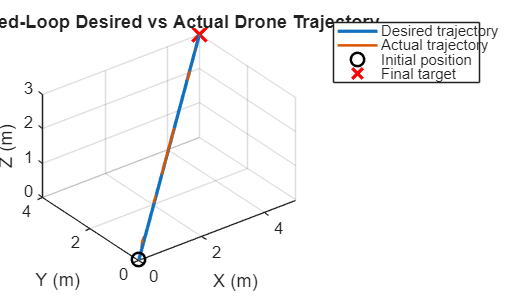


%% ========================================================
% 13. Initialize EKF
% ========================================================

% Initial position estimate

p_est = p;

% Initial velocity estimate

v_est = zeros(3,1);

% Initial attitude estimate

R_est = R;

% Initial accelerometer bias estimate

ba_est = zeros(3,1);

% Initial gyroscope bias estimate

bg_est = zeros(3,1);


%% ========================================================
% 14. EKF covariance
% ========================================================

P_cov = eye(15) * 0.01;


%% ========================================================
% 15. EKF measurement covariance
% ========================================================

R_visual = diag([
    sigma_position^2
    sigma_position^2
    sigma_position^2
    sigma_camera_angle^2
    sigma_camera_angle^2
    sigma_camera_angle^2
]);


%% ========================================================
% 16. EKF process noise
% ========================================================

Q = zeros(15);

Q(1:3,1:3) = ...
    1e-5 * eye(3);

Q(4:6,4:6) = ...
    1e-3 * eye(3);

Q(7:9,7:9) = ...
    1e-4 * eye(3);

Q(10:12,10:12) = ...
    1e-6 * eye(3);

Q(13:15,13:15) = ...
    1e-6 * eye(3);


%% ========================================================
% 17. MAIN CLOSED-LOOP SIMULATION
% ========================================================

for k = 1:numSamples


    %% ====================================================
    % A. Store current actual drone state
    % ====================================================

    p_actual = p;

    v_actual = v;

    R_actual = R;

    omega_actual = omega;


    p_history(k,:) = p_actual';

    v_history(k,:) = v_actual';

    R_history(:,:,k) = R_actual;

    omega_history(k,:) = omega_actual';


    %% ====================================================
    % B. Calculate actual acceleration
    %
    % Current applied thrust is:
    %
    %       F_body = [0 0 T]^T
    %
    % World-frame force:
    %
    %       F_world = R F_body
    %
    % Dynamics:
    %
    %       a = g + F_world/m
    % ====================================================

    F_body_applied = ...
        T_applied * e3;

    F_world_applied = ...
        R_actual * F_body_applied;

    a_true = ...
        g + F_world_applied/m;

    a_true_history(k,:) = ...
        a_true';


    %% ====================================================
    % C. Generate camera position measurement
    %
    % z_p = p + noise
    % ====================================================

    position_noise = ...
        sigma_position * randn(3,1);

    p_camera = ...
        p_actual + position_noise;

    p_camera_history(k,:) = ...
        p_camera';


    %% ====================================================
    % D. Generate camera orientation measurement
    %
    % R_camera = R_true Exp([delta_theta]x)
    % ====================================================

    delta_theta_camera = ...
        sigma_camera_angle * randn(3,1);

    R_camera = ...
        R_actual * ...
        expm(skew(delta_theta_camera));


    % Project onto SO(3)

    [U,~,V] = svd(R_camera);

    R_camera = U*V';

    if det(R_camera) < 0

        U(:,3) = -U(:,3);

        R_camera = U*V';

    end

    R_camera_history(:,:,k) = ...
        R_camera;


    %% ====================================================
    % E. Generate IMU accelerometer measurement
    %
    % Specific force:
    %
    %       f = R^T(a-g)
    %
    % Measurement:
    %
    %       a_imu = f + b_a + noise
    % ====================================================

    specific_force = ...
        R_actual' * ...
        (a_true - g);

    accel_noise = ...
        sigma_acceleration * randn(3,1);

    a_imu = ...
        specific_force ...
        + accel_bias(:) ...
        + accel_noise;

    a_imu_history(k,:) = ...
        a_imu';


    %% ====================================================
    % F. Generate IMU gyroscope measurement
    %
    % omega_imu = omega + bias + noise
    % ====================================================

    gyro_noise = ...
        sigma_gyro * randn(3,1);

    omega_imu = ...
        omega_actual ...
        + gyro_bias(:) ...
        + gyro_noise;

    omega_imu_history(k,:) = ...
        omega_imu';


    %% ====================================================
    % G. EKF prediction
    % ====================================================

    % Remove estimated sensor biases

    a_corrected = ...
        a_imu - ba_est;

    omega_corrected = ...
        omega_imu - bg_est;


    if k > 1

        %% Position prediction

        p_est = ...
            p_est ...
            + v_est*dt ...
            + 0.5 * ...
              (R_est*a_corrected + g) * dt^2;


        %% Velocity prediction

        v_est = ...
            v_est ...
            + ...
              (R_est*a_corrected + g) * dt;


        %% Attitude prediction

        R_est = ...
            R_est * ...
            expm( ...
                skew(omega_corrected*dt) ...
            );


        %% Project attitude onto SO(3)

        [U,~,V] = svd(R_est);

        R_est = U*V';

        if det(R_est) < 0

            U(:,3) = -U(:,3);

            R_est = U*V';

        end

    end


    %% ====================================================
    % H. EKF error-state transition matrix
    % ====================================================

    F = eye(15);


    % Position error due to velocity error

    F(1:3,4:6) = ...
        eye(3)*dt;


    % Velocity error due to attitude error

    F(4:6,7:9) = ...
        -R_est * ...
        skew(a_corrected) * dt;


    % Velocity error due to accelerometer bias

    F(4:6,10:12) = ...
        -R_est * dt;


    % Attitude error propagation

    F(7:9,7:9) = ...
        expm( ...
            -skew(omega_corrected*dt) ...
        );


    % Attitude error due to gyro bias

    F(7:9,13:15) = ...
        -eye(3)*dt;


    %% ====================================================
    % I. EKF covariance prediction
    % ====================================================

    P_cov = ...
        F * P_cov * F' + Q;


    %% ====================================================
    % J. Visual position innovation
    % ====================================================

    position_innovation = ...
        p_camera - p_est;


    %% ====================================================
    % K. Visual attitude innovation
    %
    % Right attitude error:
    %
    % delta_theta =
    % Log(R_est^T R_camera)
    % ====================================================

    R_error = ...
        R_est' * R_camera;

    delta_theta = ...
        logSO3(R_error);


    %% ====================================================
    % L. Combined measurement innovation
    % ====================================================

    innovation = [
        position_innovation;
        delta_theta
    ];


    %% ====================================================
    % M. Measurement matrix
    % ====================================================

    H = zeros(6,15);

    H(1:3,1:3) = eye(3);

    H(4:6,7:9) = eye(3);


    %% ====================================================
    % N. Innovation covariance
    % ====================================================

    S = ...
        H * P_cov * H' ...
        + R_visual;


    %% ====================================================
    % O. Kalman gain
    % ====================================================

    K = ...
        P_cov * H' / S;


    %% ====================================================
    % P. Estimate error state
    % ====================================================

    delta_x = ...
        K * innovation;


    %% ====================================================
    % Q. Inject error into nominal state
    % ====================================================

    % Position

    p_est = ...
        p_est + delta_x(1:3);


    % Velocity

    v_est = ...
        v_est + delta_x(4:6);


    % Attitude

    R_est = ...
        R_est * ...
        expm( ...
            skew(delta_x(7:9)) ...
        );


    % Accelerometer bias

    ba_est = ...
        ba_est + delta_x(10:12);


    % Gyroscope bias

    bg_est = ...
        bg_est + delta_x(13:15);


    %% ====================================================
    % R. Project estimated attitude onto SO(3)
    % ====================================================

    [U,~,V] = svd(R_est);

    R_est = U*V';

    if det(R_est) < 0

        U(:,3) = -U(:,3);

        R_est = U*V';

    end


    %% ====================================================
    % S. Joseph-form covariance update
    % ====================================================

    I_KH = ...
        eye(15) - K*H;

    P_cov = ...
        I_KH * P_cov * I_KH' ...
        + K * R_visual * K';


    %% ====================================================
    % T. Estimated angular velocity
    % ====================================================

    omega_est = ...
        omega_imu - bg_est;


    %% ====================================================
    % U. Store EKF estimate
    % ====================================================

    p_est_history(k,:) = ...
        p_est';

    v_est_history(k,:) = ...
        v_est';

    R_est_history(:,:,k) = ...
        R_est;

    omega_est_history(k,:) = ...
        omega_est';

    ba_est_history(k,:) = ...
        ba_est';

    bg_est_history(k,:) = ...
        bg_est';


    %% ====================================================
    % V. Position tracking error
    %
    % This is the error actually seen by the controller.
    % ====================================================

    e_p = ...
        pd(k,:)' - p_est;


    %% ====================================================
    % W. Velocity tracking error
    % ====================================================

    e_v = ...
        vd(k,:)' - v_est;


    position_error_history(k,:) = ...
        e_p';


    velocity_error_history(k,:) = ...
        e_v';


    position_error_magnitude(k) = ...
        norm(e_p);


    %% ====================================================
    % X. SO(3) POSITION CONTROLLER
    %
    % Same control logic as Step 5.
    %
    % a_cmd =
    % a_d + Kp e_p + Kv e_v
    % ====================================================

    a_cmd = ...
        ad(k,:)' ...
        + Kp*e_p ...
        + Kv*e_v;


    acceleration_command(k,:) = ...
        a_cmd';


    %% ====================================================
    % Y. Desired force
    %
    % F_d = m(a_cmd - g)
    % ====================================================

    F_desired = ...
        m * (a_cmd - g);


    force_command(k,:) = ...
        F_desired';


    %% ====================================================
    % Z. Desired thrust direction
    % ====================================================

    if norm(F_desired) < 1e-8

        b3d = e3;

    else

        b3d = ...
            F_desired / norm(F_desired);

    end


    %% ====================================================
    % AA. Desired yaw
    %
    % Yaw follows horizontal desired velocity.
    % ====================================================

    if norm(vd(k,1:2)) > 1e-4

        yaw_d = ...
            atan2( ...
                vd(k,2), ...
                vd(k,1));

    else

        yaw_d = 0;

    end


    b1_heading = [
        cos(yaw_d);
        sin(yaw_d);
        0
    ];


    %% ====================================================
    % AB. Construct desired attitude
    % ====================================================

    b2d_temp = ...
        cross(b3d,b1_heading);


    if norm(b2d_temp) < 1e-8

        b1_heading = [1;0;0];

        b2d_temp = ...
            cross(b3d,b1_heading);

    end


    b2d = ...
        b2d_temp / norm(b2d_temp);


    b1d = ...
        cross(b2d,b3d);


    Rd = [
        b1d  b2d  b3d
    ];


    %% ====================================================
    % AC. Project desired attitude onto SO(3)
    % ====================================================

    [U,~,V] = svd(Rd);

    Rd = U*V';

    if det(Rd) < 0

        U(:,3) = -U(:,3);

        Rd = U*V';

    end


    R_desired_history(:,:,k) = ...
        Rd;


    %% ====================================================
    % AD. SO(3) attitude error
    %
    % e_R =
    % 1/2 vee(Rd^T R - R^T Rd)
    % ====================================================

    E_R = ...
        0.5 * ...
        ( ...
        Rd' * R_est ...
        - ...
        R_est' * Rd ...
        );


    e_R = ...
        vee(E_R);


    attitude_error_history(k,:) = ...
        e_R';


    %% ====================================================
    % AE. Desired angular velocity
    %
    % Same simplified assumption as Step 5.
    % ====================================================

    omega_d = ...
        zeros(3,1);


    %% ====================================================
    % AF. Angular velocity error
    % ====================================================

    e_omega = ...
        omega_est - omega_d;


    %% ====================================================
    % AG. Geometric torque controller
    %
    % tau =
    % -KR e_R
    % -Komega e_omega
    % + omega x J omega
    % ====================================================

    tau = ...
        -KR*e_R ...
        -Komega*e_omega ...
        + cross( ...
            omega_est, ...
            J*omega_est);


    torque_command(k,:) = ...
        tau';


    %% ====================================================
    % AH. Desired thrust magnitude
    % ====================================================

    T_cmd = ...
        norm(F_desired);


    desired_thrust(k) = ...
        T_cmd;


    %% ====================================================
    % AI. Apply command to drone dynamics
    %
    % The command calculated at this timestep is held
    % constant over the next dt interval.
    % ====================================================

    if k < numSamples

        %% Thrust force in body frame

        F_body = ...
            T_cmd * e3;


        %% Convert thrust to world frame

        F_world = ...
            R_actual * F_body;


        %% Translational dynamics

        p_dot = ...
            v_actual;

        v_dot = ...
            g + F_world/m;


        %% Rotational kinematics

        R_dot = ...
            R_actual * ...
            skew(omega_actual);


        %% Rotational dynamics

        omega_dot = ...
            J \ ...
            ( ...
            tau ...
            - cross( ...
                omega_actual, ...
                J*omega_actual) ...
            );


        %% Forward Euler integration

        p = ...
            p_actual + p_dot*dt;

        v = ...
            v_actual + v_dot*dt;

        omega = ...
            omega_actual + omega_dot*dt;


        %% SO(3) attitude integration

        R = ...
            R_actual * ...
            expm( ...
                skew(omega_actual*dt) ...
            );


        %% Project actual attitude onto SO(3)

        [U,~,V] = svd(R);

        R = U*V';

        if det(R) < 0

            U(:,3) = -U(:,3);

            R = U*V';

        end


        %% Store command that is actually applied
        % during the next interval

        T_applied = T_cmd;

        tau_applied = tau;

    end

end

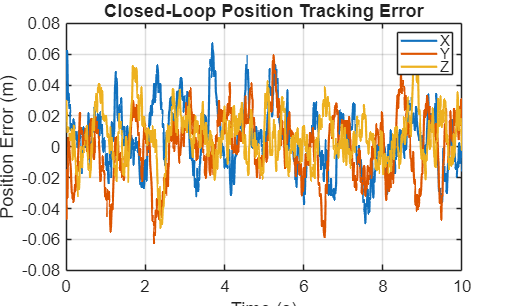



%% ========================================================
% 18. Final actual ground truth
%
% In this closed-loop simulation, the actual dynamics
% trajectory is the ground truth.
% ========================================================

p_true = ...
    p_history;

v_true = ...
    v_history;

a_true = ...
    a_true_history;

R_true = ...
    R_history;

omega_true = ...
    omega_history;


%% ========================================================
% 19. Calculate position tracking metrics
% ========================================================

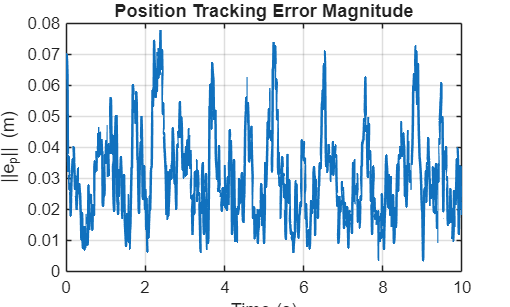


position_RMSE = ...
    sqrt( ...
        mean( ...
            position_error_history.^2, ...
            1));


velocity_RMSE = ...
    sqrt( ...
        mean( ...
            velocity_error_history.^2, ...
            1));


maximum_position_error = ...
    max(position_error_magnitude);



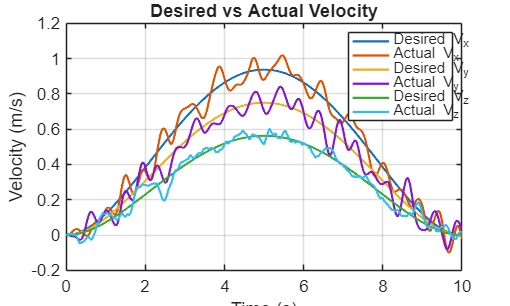

final_position_error = ...
    position_error_magnitude(end);


%% ========================================================
% 20. Calculate attitude error magnitude
% ========================================================

attitude_error_norm = ...
    sqrt( ...
        sum( ...
            attitude_error_history.^2, ...
            2));


attitude_RMSE = ...
    sqrt( ...
        mean( ...
            attitude_error_norm.^2));


%% ========================================================
% 21. Rotation matrix validity
% ========================================================

rotation_orthogonality_error = ...
    zeros(numSamples,1);

rotation_determinant_error = ...
    zeros(numSamples,1);


for k = 1:numSamples

    Rk = ...
        R_history(:,:,k);

    rotation_orthogonality_error(k) = ...
        norm( ...
            Rk'*Rk - eye(3), ...
            'fro');

    rotation_determinant_error(k) = ...
        abs(det(Rk)-1);

end


%% ========================================================
% 22. Plot desired vs actual 3D trajectory
% ========================================================

figure;


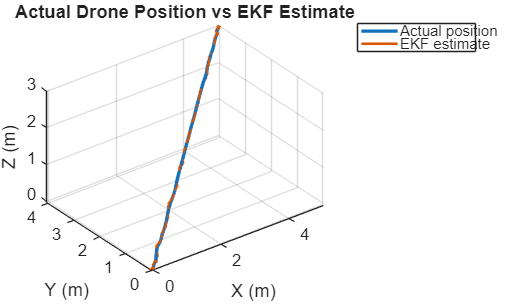

plot3( ...
    pd(:,1), ...
    pd(:,2), ...
    pd(:,3), ...
    'LineWidth',2);

hold on;

plot3( ...
    p_history(:,1), ...
    p_history(:,2), ...
    p_history(:,3), ...
    'LineWidth',1.5);

plot3( ...
    pd(1,1), ...
    pd(1,2), ...
    pd(1,3), ...
    'ko', ...
    'MarkerSize',8, ...
    'LineWidth',1.5);

plot3( ...
    pd(end,1), ...
    pd(end,2), ...
    pd(end,3), ...
    'rx', ...
    'MarkerSize',12, ...
    'LineWidth',2);

grid on;

axis equal;

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

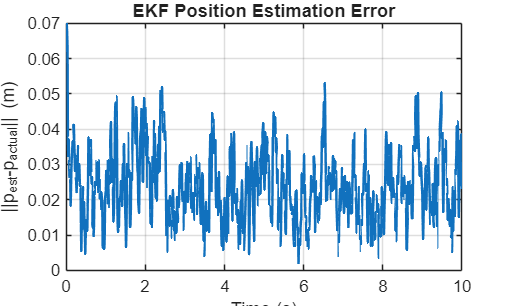


title('Closed-Loop Desired vs Actual Drone Trajectory');

legend( ...
    'Desired trajectory', ...
    'Actual trajectory', ...
    'Initial position', ...
    'Final target');

view(3);


%% ========================================================
% 23. Position tracking error
% ========================================================

figure;

plot( ...
    t, ...
    position_error_history(:,1), ...
    'LineWidth',1.3);

hold on;

plot( ...
    t, ...
    position_error_history(:,2), ...
    'LineWidth',1.3);

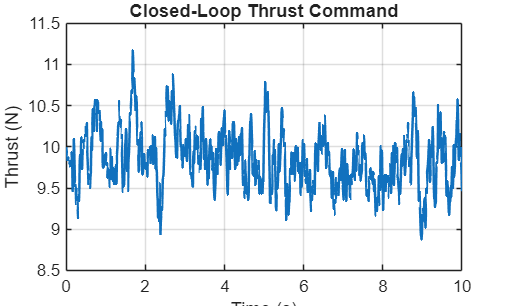


plot( ...
    t, ...
    position_error_history(:,3), ...
    'LineWidth',1.3);

xlabel('Time (s)');
ylabel('Position Error (m)');

title('Closed-Loop Position Tracking Error');

legend( ...
    'X', ...
    'Y', ...
    'Z');

grid on;



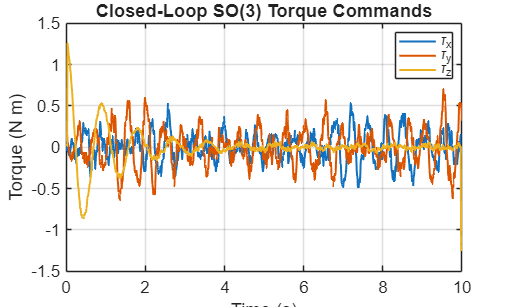

%% ========================================================
% 24. Position error magnitude
% ========================================================

figure;

plot( ...
    t, ...
    position_error_magnitude, ...
    'LineWidth',1.5);

xlabel('Time (s)');
ylabel('||e_p|| (m)');

title('Position Tracking Error Magnitude');

grid on;


%% ========================================================
% 25. Desired vs actual velocity
% ========================================================

figure;

plot( ...
    t, ...
    vd(:,1), ...
    'LineWidth',1.3);

hold on;

plot( ...
    t, ...
    v_history(:,1), ...
    'LineWidth',1.3);

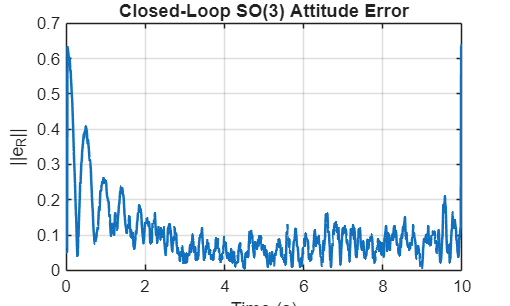


plot( ...
    t, ...
    vd(:,2), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    v_history(:,2), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    vd(:,3), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    v_history(:,3), ...
    'LineWidth',1.3);


xlabel('Time (s)');
ylabel('Velocity (m/s)');

title('Desired vs Actual Velocity');

legend( ...
    'Desired V_x', ...
    'Actual V_x', ...
    'Desired V_y', ...
    'Actual V_y', ...
    'Desired V_z', ...
    'Actual V_z');

STEP 6 - CLOSED-LOOP DRONE SIMULATION RESULTS



FINAL TARGET:



grid on;


X = 5.0000 m



%% ========================================================
% 26. EKF position estimate vs actual position
% ========================================================

Y = 4.0000 m



figure;

plot3( ...
    p_history(:,1), ...
    p_history(:,2), ...
    p_history(:,3), ...
    'LineWidth',2);

Z = 3.0000 m



FINAL ACTUAL POSITION:



hold on;


X = 4.9942 m


plot3( ...
    p_est_history(:,1), ...
    p_est_history(:,2), ...
    p_est_history(:,3), ...
    'LineWidth',1.5);

Y = 4.0043 m



grid on;


Z = 3.0015 m


axis equal;

xlabel('X (m)');


POSITION RMSE:


ylabel('Y (m)');
zlabel('Z (m)');

title('Actual Drone Position vs EKF Estimate');

X = 0.0207 m



legend( ...
    'Actual position', ...
    'EKF estimate');

Y = 0.0207 m



view(3);



Z = 0.0177 m


%% ========================================================
% 27. EKF position error
% ========================================================

estimation_position_error = ...
    p_est_history - p_history;


Maximum position tracking error = 0.0776 m



estimation_position_error_norm = ...
    sqrt( ...
        sum( ...
            estimation_position_error.^2, ...
            2));

Final position tracking error = 0.0224 m



VELOCITY RMSE:



figure;

plot( ...
    t, ...
    estimation_position_error_norm, ...
    'LineWidth',1.5);

X = 0.0885 m/s


Y = 0.0942 m/s


xlabel('Time (s)');
ylabel('||p_{est}-p_{actual}|| (m)');

title('EKF Position Estimation Error');

Z = 0.0636 m/s



grid on;


%% ========================================================


EKF final position error = 0.0295 m


% 28. Thrust command
% ========================================================

figure;


EKF position RMSE = 0.0262 m


plot( ...
    t, ...
    desired_thrust, ...
    'LineWidth',1.5);



Attitude RMSE = 0.1374 rad


xlabel('Time (s)');
ylabel('Thrust (N)');

title('Closed-Loop Thrust Command');


Attitude RMSE = 7.8737 degrees


grid on;


%% ========================================================
% 29. Torque command


Maximum thrust = 11.1692 N


% ========================================================

figure;

plot( ...
    t, ...
    torque_command(:,1), ...
    'LineWidth',1.2);

Average thrust = 9.8454 N



Maximum torque:



hold on;

plot( ...
    t, ...
    torque_command(:,2), ...
    'LineWidth',1.2);

tau_x = 0.5329 N m


tau_y = 0.7033 N m


plot( ...
    t, ...
    torque_command(:,3), ...
    'LineWidth',1.2);

tau_z = 1.2635 N m



xlabel('Time (s)');
ylabel('Torque (N m)');


SO(3) validity:



title('Closed-Loop SO(3) Torque Commands');

legend( ...
    '\tau_x', ...
    '\tau_y', ...
    '\tau_z');

Maximum orthogonality error = 1.2773e-15


Maximum determinant error = 8.8818e-16


grid on;



%% ========================================================
% 30. Attitude error
% ========================================================

figure;

plot( ...
    t, ...
    attitude_error_norm, ...
    'LineWidth',1.5);

xlabel('Time (s)');
ylabel('||e_R||');

title('Closed-Loop SO(3) Attitude Error');

grid on;


%% ========================================================
% 31. Display results
% ========================================================

fprintf('\n');
fprintf('================================================\n');
fprintf('STEP 6 - CLOSED-LOOP DRONE SIMULATION RESULTS\n');
fprintf('================================================\n');


fprintf('\nFINAL TARGET:\n');

fprintf( ...
    'X = %.4f m\n', ...
    pd(end,1));

fprintf( ...
    'Y = %.4f m\n', ...
    pd(end,2));

fprintf( ...
    'Z = %.4f m\n', ...
    pd(end,3));


fprintf('\nFINAL ACTUAL POSITION:\n');

fprintf( ...
    'X = %.4f m\n', ...
    p_history(end,1));

fprintf( ...
    'Y = %.4f m\n', ...
    p_history(end,2));

fprintf( ...
    'Z = %.4f m\n', ...
    p_history(end,3));


fprintf('\nPOSITION RMSE:\n');

fprintf( ...
    'X = %.4f m\n', ...
    position_RMSE(1));

fprintf( ...
    'Y = %.4f m\n', ...
    position_RMSE(2));


Step 6 closed-loop results saved to drone_toy_model.mat



fprintf( ...
    'Z = %.4f m\n', ...
    position_RMSE(3));


fprintf( ...
    '\nMaximum position tracking error = %.4f m\n', ...
    maximum_position_error);


fprintf( ...
    'Final position tracking error = %.4f m\n', ...
    final_position_error);


fprintf('\nVELOCITY RMSE:\n');

fprintf( ...
    'X = %.4f m/s\n', ...
    velocity_RMSE(1));

fprintf( ...
    'Y = %.4f m/s\n', ...
    velocity_RMSE(2));

fprintf( ...
    'Z = %.4f m/s\n', ...
    velocity_RMSE(3));


fprintf( ...
    '\nEKF final position error = %.4f m\n', ...
    estimation_position_error_norm(end));


fprintf( ...
    'EKF position RMSE = %.4f m\n', ...
    sqrt(mean(estimation_position_error_norm.^2)));


fprintf( ...
    '\nAttitude RMSE = %.4f rad\n', ...
    attitude_RMSE);


fprintf( ...
    'Attitude RMSE = %.4f degrees\n', ...
    rad2deg(attitude_RMSE));


fprintf( ...
    '\nMaximum thrust = %.4f N\n', ...
    max(desired_thrust));


fprintf( ...
    'Average thrust = %.4f N\n', ...
    mean(desired_thrust));


fprintf('\nMaximum torque:\n');

fprintf( ...
    'tau_x = %.4f N m\n', ...
    max(abs(torque_command(:,1))));

fprintf( ...
    'tau_y = %.4f N m\n', ...
    max(abs(torque_command(:,2))));

fprintf( ...
    'tau_z = %.4f N m\n', ...
    max(abs(torque_command(:,3))));


fprintf('\nSO(3) validity:\n');

fprintf( ...
    'Maximum orthogonality error = %.4e\n', ...
    max(rotation_orthogonality_error));

fprintf( ...
    'Maximum determinant error = %.4e\n', ...
    max(rotation_determinant_error));


fprintf('\n================================================\n');


%% ========================================================
% 32. Save Step 6 results
% ========================================================

save( ...
    'drone_toy_model.mat', ...
    'p0', ...
    'pf', ...
    'v0', ...
    'vf', ...
    'a0', ...
    'af', ...
    'T', ...
    't', ...
    'dt', ...
    'pd', ...
    'vd', ...
    'ad', ...
    'p_true', ...
    'v_true', ...
    'a_true', ...
    'R_true', ...
    'omega_true', ...
    'p_history', ...
    'v_history', ...
    'R_history', ...
    'omega_history', ...
    'p_camera_history', ...
    'R_camera_history', ...
    'a_imu_history', ...
    'omega_imu_history', ...
    'p_est_history', ...
    'v_est_history', ...
    'R_est_history', ...
    'omega_est_history', ...
    'ba_est_history', ...
    'bg_est_history', ...
    'acceleration_command', ...
    'force_command', ...
    'desired_thrust', ...
    'R_desired_history', ...
    'attitude_error_history', ...
    'torque_command', ...
    'position_error_history', ...
    'velocity_error_history', ...
    'position_error_magnitude', ...
    'estimation_position_error', ...
    'estimation_position_error_norm', ...
    'position_RMSE', ...
    'velocity_RMSE', ...
    'attitude_RMSE', ...
    'sigma_position', ...
    'sigma_camera_angle', ...
    'sigma_acceleration', ...
    'sigma_gyro', ...
    'accel_bias', ...
    'gyro_bias', ...
    'attitude_error_norm', ...
    'maximum_position_error', ...
    'final_position_error', ...
    'rotation_orthogonality_error', ...
    'rotation_determinant_error');

fprintf('\nStep 6 closed-loop results saved to drone_toy_model.mat\n');


%% ========================================================
% LOCAL FUNCTIONS
% ========================================================

function S = skew(v)

    S = [
         0    -v(3)  v(2);
         v(3)  0    -v(1);
        -v(2) v(1)   0
    ];

end


function v = vee(S)

    v = [
        S(3,2);
        S(1,3);
        S(2,1)
    ];

end


function v = logSO3(R)

    % Numerical protection

    cos_theta = ...
        (trace(R)-1)/2;

    cos_theta = ...
        max(-1,min(1,cos_theta));

    theta = ...
        acos(cos_theta);


    if theta < 1e-8

        v = zeros(3,1);

    else

        v = ...
            theta/(2*sin(theta)) * ...
            [
                R(3,2)-R(2,3);
                R(1,3)-R(3,1);
                R(2,1)-R(1,2)
            ];

    end

end